# Motor Generator 1 Component

Copyright 2021 The Mathworks, Inc.

## Open the Model

mdl = "MotorGenerator1Basic_test_harness";
if not(bdIsLoaded(mdl))
  % A callback function in the model runs the setup script.
  open_system(mdl)
else
  MotorGenerator1Basic_setup
end

## Load Inputs to Workspace

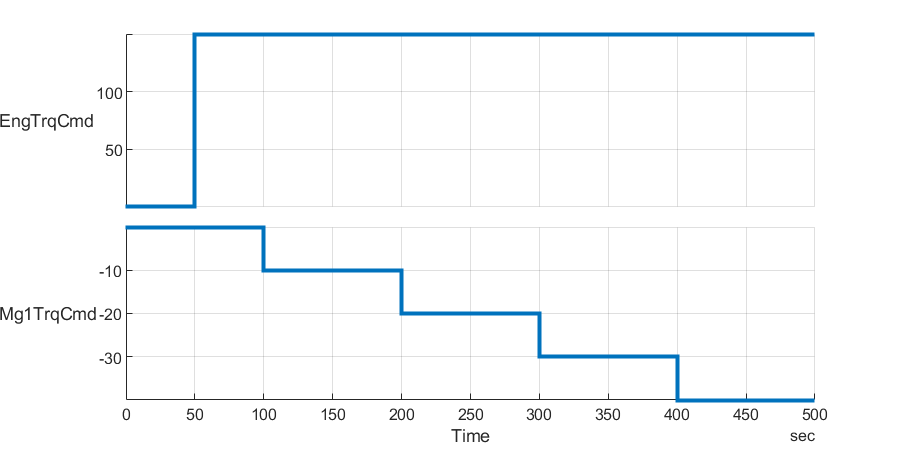

fig = figure;
[inputSignals_testMG1, inputBus_testMG1, t_end] = ...
  MotorGenerator1Basic_inputs( "PlotParent",fig, "InputPattern","generate" );

## Run Simulation

% Override initial conditions and block parameters
initial.motorDriveUnit_spd_rpm = 0;

% Set simulation input
in = Simulink.SimulationInput(mdl);
in = in.setModelParameter('StopTime',num2str(t_end));

% Run simulation
out = sim(in);

## Visualize Simulation Result

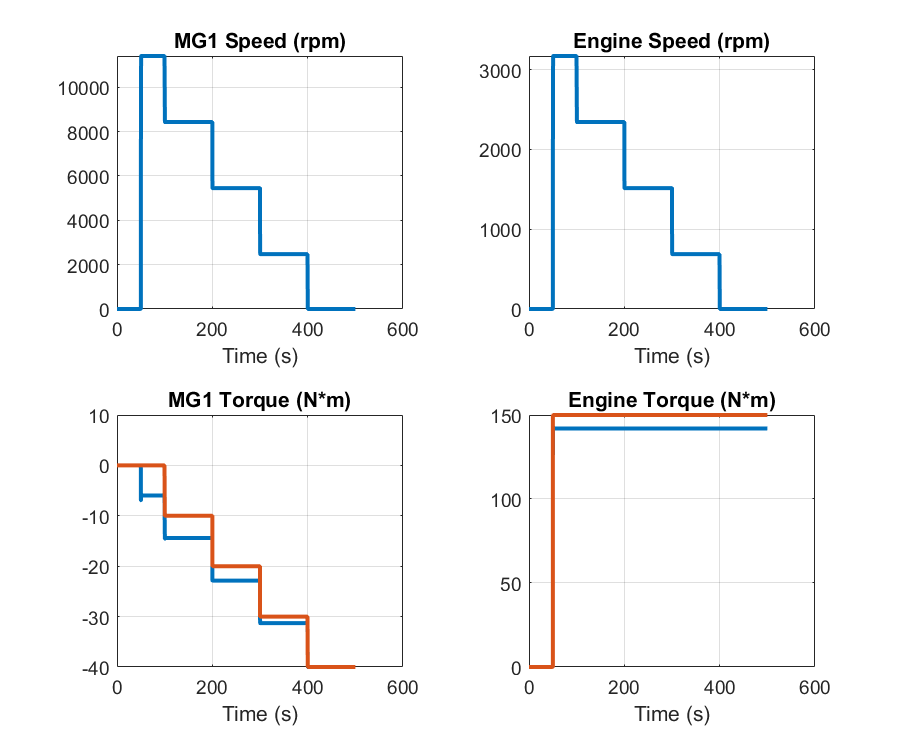

fig = figure;
MotorGenerator1Basic_plot_result("PlotParent",fig, "Dataset",out.logsout)